clc
clear all
cd 01/

## 1.a

p = 0.6;
n = 4;

rightAnswer = p + (1 - p)/n;
fprintf('The student selects the right answer: %d%%', rightAnswer*100);

The student selects the right answer: 70%

## 1.b

p = 0.7;
n = 5;

knowsAnswer = p * n / (1 + (n - 1) * p);
fprintf('The student knows the answer, given they select the right one: %.1f%%', knowsAnswer*100);

The student knows the answer, given they select the right one: 92.1%

## Plot e.g.

% f(x) = x²
% g(x) = 1 - x⁴

x = linspace(0,1);
fx =  x.^2;
gx = 1 - x.^4;

plot(x, fx, 'b--', x, gx, 'k-')
grid on
ylim([0 1.1])
title('title')
xlabel('x-axis')
ylabel('y-axis')
legend('f(x)', 'g(x)', Location='west')

## 1.c

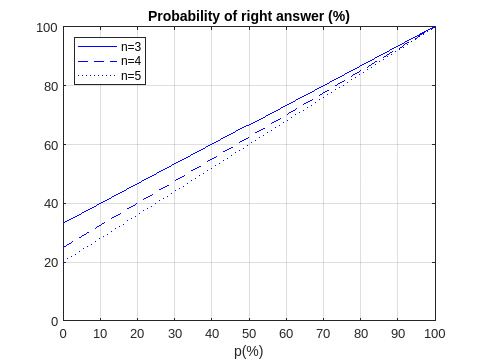

n1 = 3;
n2 = 4;
n3 = 5;

x = linspace(0,1);
fx = x + (1 - x)/n1;
gx = x + (1 - x)/n2;
hx = x + (1 - x)/n3;

plot(x*100, fx*100, 'b-', x*100, gx*100, 'b--', x*100, hx*100, 'b:')
grid on
yticks(0:20:100);
xticks(0:10:100);
ylim([0 100])
xlabel('p(%)')
title("Probability of right answer (%)")
legend('n=3','n=4','n=5',Location='northwest')

## 1.d

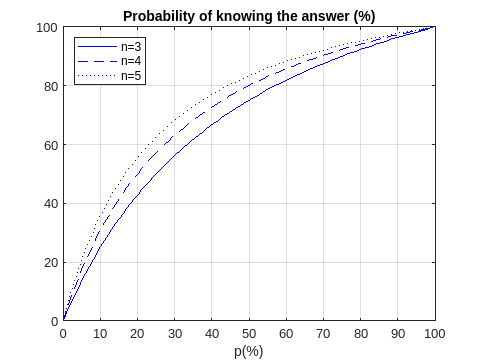

n1 = 3;
n2 = 4;
n3 = 5;

x = linspace(0,1);
fx = x * n1 ./ (1 + (n1 - 1) * x);
gx = x * n2 ./ (1 + (n2 - 1) * x);
hx = x * n3 ./ (1 + (n3 - 1) * x);

plot(x*100, fx*100, 'b-', x*100, gx*100, 'b--', x*100, hx*100, 'b:')
grid on
yticks(0:20:100);
xticks(0:10:100);
ylim([0 100])
xlabel('p(%)')
title("Probability of knowing the answer (%)")
legend('n=3','n=4','n=5',Location='northwest')